dt=0.1

dt = 0.1000

t=0:dt:50

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


Pm=zeros(1,length(t));
Pm(1)=5000; %Posicion Inicial

a1=zeros(1,length(t));
a1(1)=-9.81;

v=zeros(1,length(t));
v(1)=0;

f=@(z,v)-9.81+(0.2/80)*v^2

f = function_handle with value:
    @(z,v)-9.81+(0.2/80)*v^2


dydt=@(y)[y(2); f(y(1),y(2))]

dydt = function_handle with value:
    @(y)[y(2);f(y(1),y(2))]


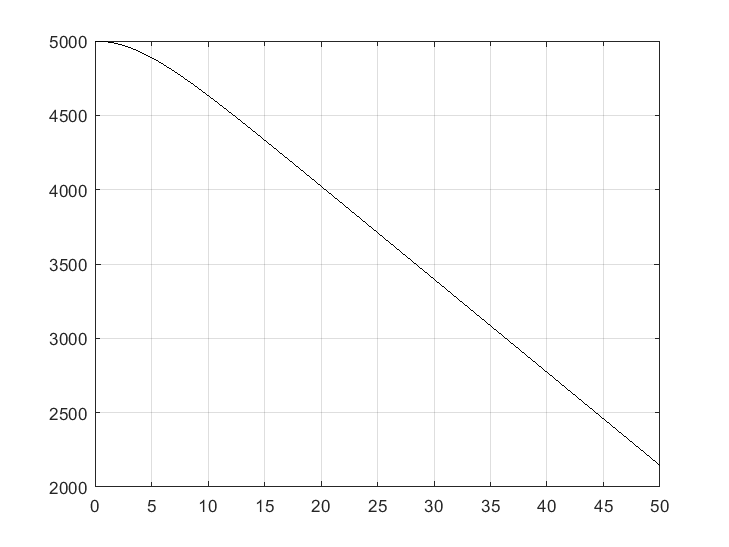


for i5=1:length(t)-1
    z0=[Pm(i5);v(i5)];
    k1=dydt(z0);
    k2=dydt(z0+(dt*k1)/2);
    k3=dydt(z0+(dt*k2)/2);
    k4=dydt(z0+dt*k3);
    
    Pm(i5+1)=Pm(i5)+(dt/6)*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
    v(i5+1)=v(i5)+(dt/6)*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
    a1(i5+1)=f(Pm(i5),v(i5));
    if Pm(i5+1)<=0
        break
    end
end
plot(t(1:i5+1),Pm(1:i5+1),'k')
 grid on

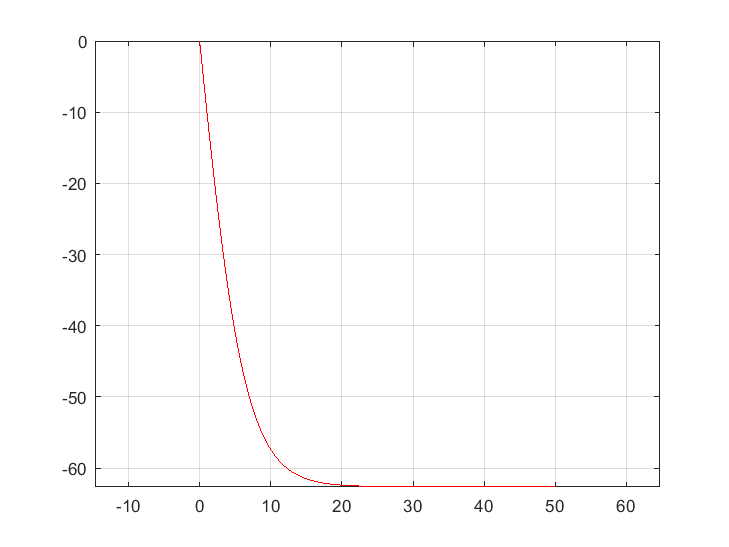

 plot(t(1:i5+1),v(1:i5+1),'r')
 axis equal
 grid on

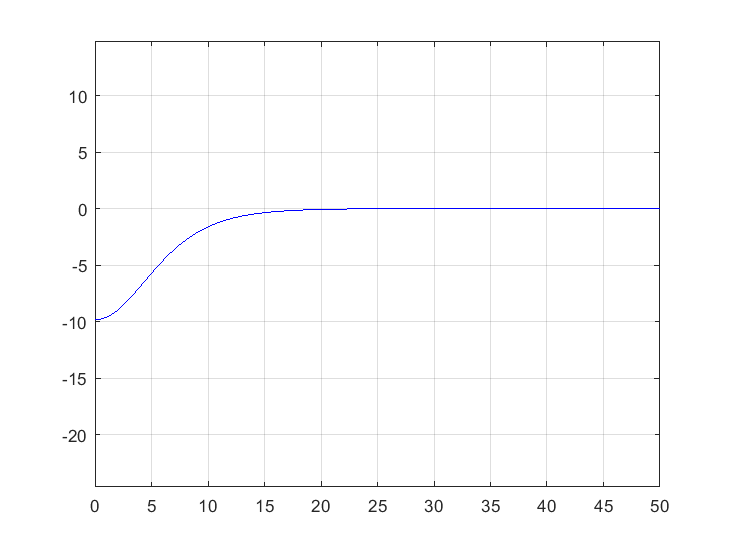

 plot(t(1:i5+1),a1(1:i5+1),'b')
 grid on
 axis equal